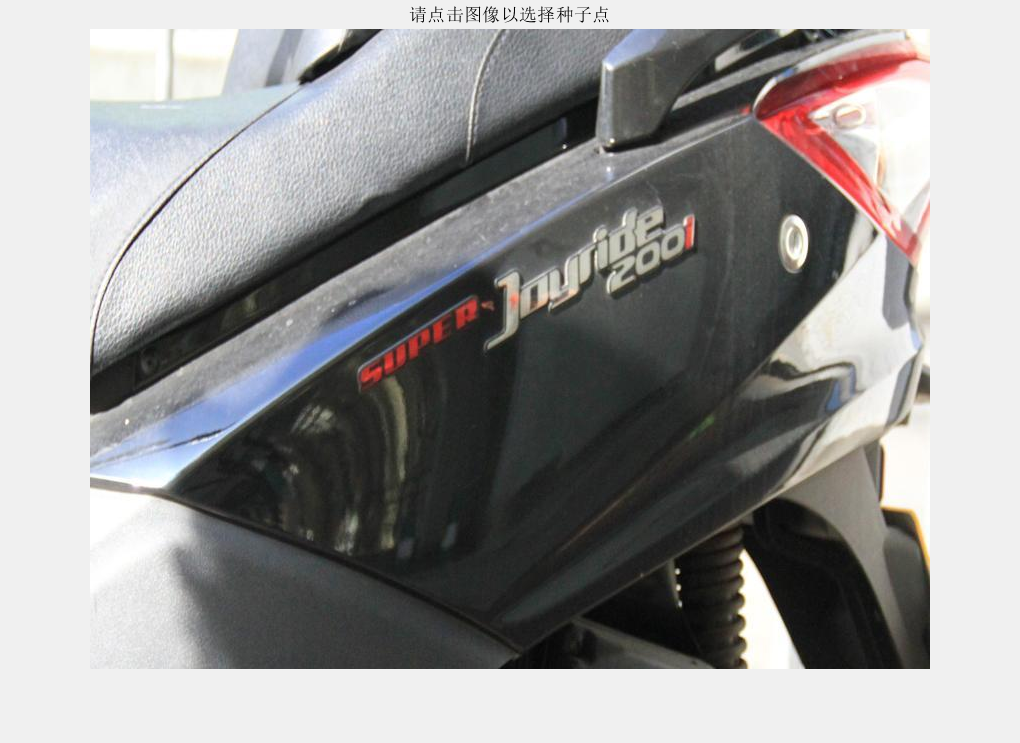

img = imread("../resources/IMG_6759.jpg");
if size(img, 3) == 3
    gray_img = rgb2gray(img); % 转为灰度图像
else
    gray_img = img;
end

% 显示图像并让用户选择种子点
figure;
imshow(img);
title('请点击图像以选择种子点');
[x, y] = ginput(1); % 交互选择种子点

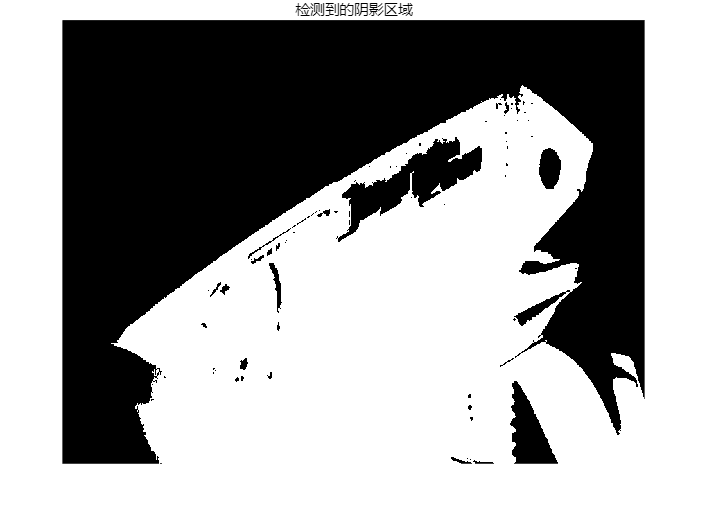

x = round(x);
y = round(y);

% 区域生长参数
seed = [y, x]; % 注意 MATLAB 图像坐标格式为 (行, 列)
threshold = 50; % 灰度值变化阈值，可根据需求调整

% 初始化区域生长
[rows, cols] = size(gray_img);
region = false(rows, cols);
region(seed(1), seed(2)) = true;
seed_gray_value = gray_img(seed(1), seed(2));

% 定义四邻域
neighbors = [-1 0; 1 0; 0 -1; 0 1];

% 区域生长算法
queue = seed; % 以队列形式存储待扩展像素
while ~isempty(queue)
    current_pixel = queue(1, :);
    queue(1, :) = []; % 出队列

    for k = 1:size(neighbors, 1)
        neighbor = current_pixel + neighbors(k, :);
        if neighbor(1) > 0 && neighbor(1) <= rows && neighbor(2) > 0 && neighbor(2) <= cols
            if ~region(neighbor(1), neighbor(2)) % 未访问过
                diff = abs(double(gray_img(neighbor(1), neighbor(2))) - double(seed_gray_value));
                if diff <= threshold
                    region(neighbor(1), neighbor(2)) = true;
                    queue = [queue; neighbor]; % 入队列
                end
            end
        end
    end
end

% 显示结果
shadow_mask = uint8(region) * 255; % 将逻辑矩阵转为图像格式
figure;
imshow(shadow_mask);
title('检测到的阴影区域');

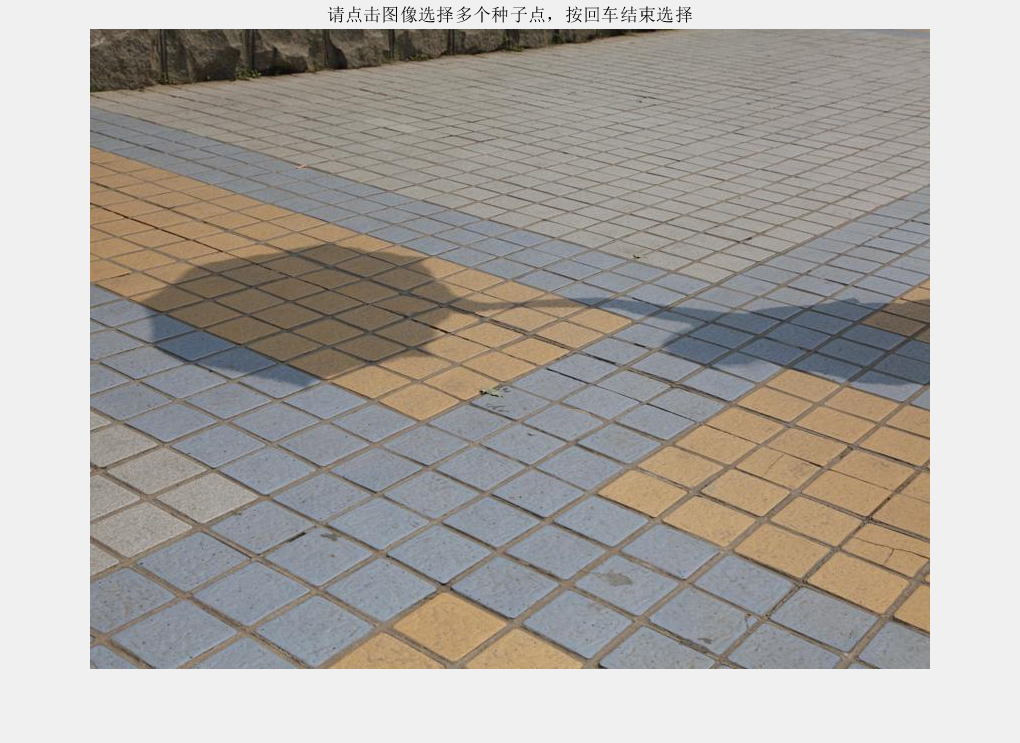

clear; clc;
% 阴影检测 - 区域生长法 (支持多个种子点)
% 允许用户选择多个种子点，结果取并集

% 读取图像
img = imread("../resources/_MG_5844.jpg");
if size(img, 3) == 3
    gray_img = rgb2gray(img); % 转为灰度图像
else
    gray_img = img;
end

% 显示图像并让用户选择多个种子点
figure;
imshow(img);
title('请点击图像选择多个种子点，按回车结束选择');
[x, y] = ginput; % 允许选择多个种子点

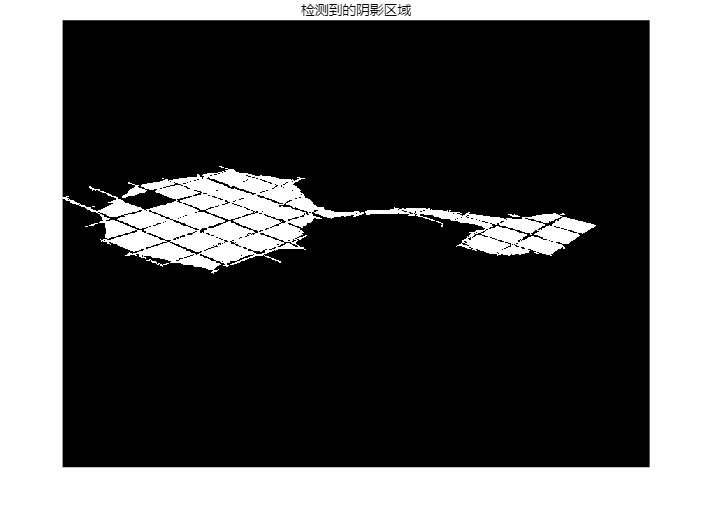

x = round(x);
y = round(y);

% 区域生长参数
threshold = 20; % 灰度值变化阈值，可根据需求调整

% 初始化区域生长
[rows, cols] = size(gray_img);
region = false(rows, cols); % 用于存储阴影区域

% 定义四邻域
neighbors = [-1 0; 1 0; 0 -1; 0 1];

% 区域生长算法函数
function region = grow_region(seed, gray_img, region, threshold, neighbors)
    [rows, cols] = size(gray_img);
    seed_gray_value = gray_img(seed(1), seed(2));
    
    % 初始化队列
    queue = seed;
    region(seed(1), seed(2)) = true;
    
    while ~isempty(queue)
        current_pixel = queue(1, :);
        queue(1, :) = []; % 出队列

        for k = 1:size(neighbors, 1)
            neighbor = current_pixel + neighbors(k, :);
            if neighbor(1) > 0 && neighbor(1) <= rows && neighbor(2) > 0 && neighbor(2) <= cols
                if ~region(neighbor(1), neighbor(2)) % 未访问过
                    diff = abs(double(gray_img(neighbor(1), neighbor(2))) - double(seed_gray_value));
                    if diff <= threshold
                        region(neighbor(1), neighbor(2)) = true;
                        queue = [queue; neighbor]; % 入队列
                    end
                end
            end
        end
    end
end

% 对每个种子点进行区域生长，取并集
for i = 1:length(x)
    seed = [y(i), x(i)]; % 注意 MATLAB 图像坐标格式为 (行, 列)
    region = grow_region(seed, gray_img, region, threshold, neighbors);
end

% 显示结果
shadow_mask = uint8(region) * 255; % 将逻辑矩阵转为图像格式
figure;
imshow(shadow_mask);
title('检测到的阴影区域');